**Question 2**

t = [192,192,196,188]';
b = [200,200,200,200]';

m = log(b./t);

% m1 = u1 + u3
% m2 = u2
% m3 = u3
% m4 = u1 + u2

% (4,3)
A = [1,0,1;
     0,1,0;
     0,0,1;
     1,1,0];

% initial guess
mu = [1,1,1]';
n_iterations = 100;
dmus = zeros(n_iterations,1);

for i=1:n_iterations
    % update
    dmu = 1./(sum(A)') .* A' * ( (m - A*mu) ./ (sum(A')'));
    mu = mu + dmu;
    
    dmus(i) = norm(dmu);
end

Plot the convergence

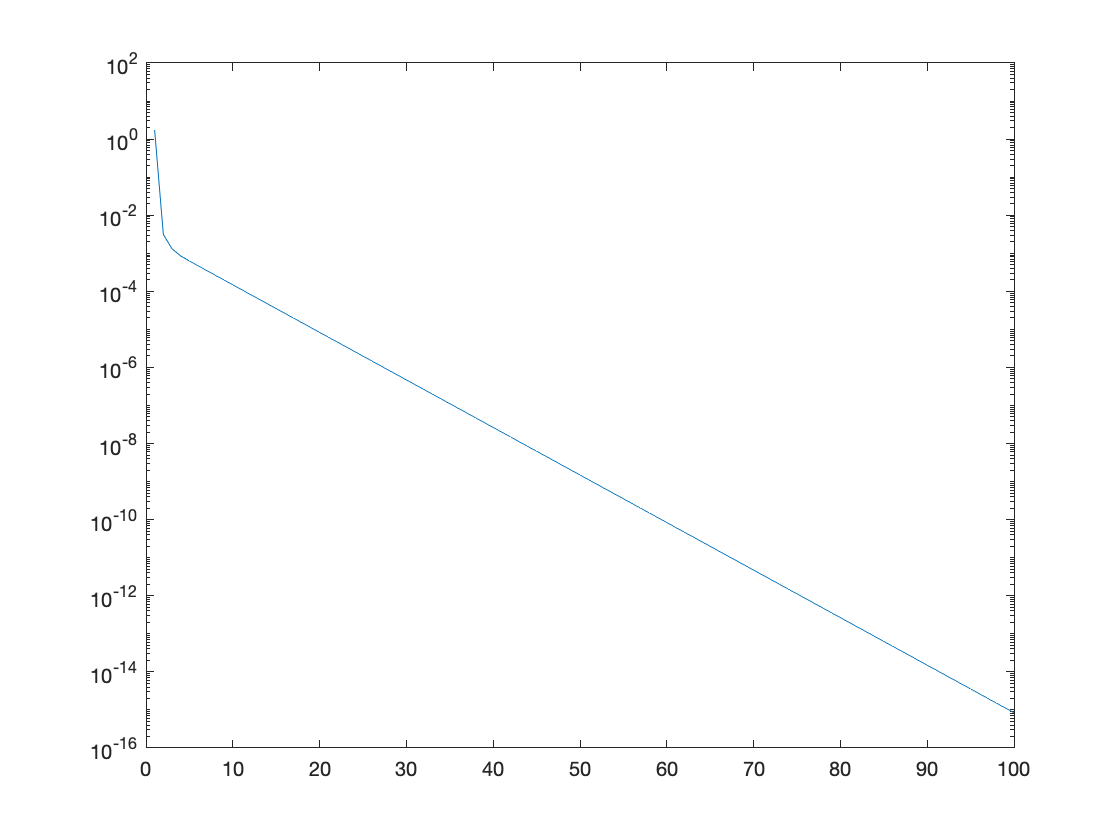

semilogy(dmus)